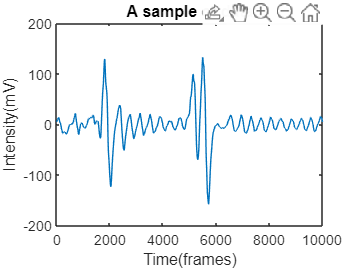


trainLen = 20000;
testLen = 10000;
initLen = 100;
table = readtable('dat.csv','NumHeaderLines',5);
valTable = readtable('dat2.csv','NumHeaderLines',5); 
% plot some of it
timeStamps = table2array(removevars(table,{'Var2'}));
data=table2array(removevars(table,{'Var1'}));
valData = table2array(removevars(valTable, {'Var1'}));
valData = valData(1:2:end);
timeStamps = timeStamps(1:2:end);
figure(10);
data = data(1:2:end);
plot(data(1:10000));
title('A sample of data');
xlabel('Time(frames)')
ylabel('Intensity(mV)')

inSize = 1; outSize = 1;
resSize = 1000;
a = 0.4; % leaking rate
rand( 'seed', 42 );
Win = (rand(resSize,1+inSize)-0.5) .* 1;
% dense W:
%W = rand(resSize,resSize)-0.5;
% sparse W:
W = sprand(resSize,resSize,0.004);
% W_mask = (W~=0); 
% W(W_mask) = (W(W_mask)-0.5);

% normalizing and setting spectral radius
disp 'Computing spectral radius...';

Computing spectral radius...


opt.disp = 0;
rhoW = abs(eigs(W,1,'LM',opt))

rhoW = 2.0246

disp 'done.'

done.


W = W .* (1.25 / rhoW);

% allocated memory for the design (collected states) matrix
X = zeros(1+inSize+resSize,trainLen-initLen);
% set the corresponding target matrix directly
Yt = data(initLen+2:trainLen+1)';

% run the reservoir with the data and collect X
x = zeros(resSize,1);
for t = 1:trainLen
	u = data(t);
	x = (1-a)*x + a*tanh( Win*[1;u] + W*x );
	if t > initLen
		X(:,t-initLen) = [1;u;x];
	end
end

% train the output by ridge regression
reg = 1e-8;  % regularization coefficient
% direct equations from texts:
X_T = X'; 
Wout = Yt*X_T * inv(X*X_T + reg*eye(1+inSize+resSize));

% using Matlab mldivide solver:
%Wout = ((X*X' + reg*eye(1+inSize+resSize)) \ (X*Yt'))'; 

Y = zeros(outSize, testLen);
u = data(trainLen+1);
for t = 1:testLen 
	x = (1-a)*x + a*tanh( Win*[1;u] + W*x );
	y = Wout*[1;u;x];
	Y(:,t) = y;
    if(y>1000)
        break
    end
	% generative mode:
    if(t>2000)
	    u = y;
    end
	% this would be a predictive mode:
    if(t<8000)
        u = data(trainLen+t+1);
    end
end

errorLen = 500;
mse = sum((data(trainLen+2:trainLen+errorLen+1)'-Y(1,1:errorLen)).^2)./errorLen;
disp( ['MSE = ', num2str( mse )] );

MSE = 0.0049645


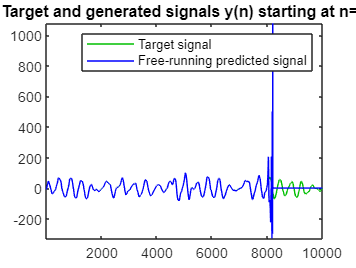


figure(1);
plot( data(trainLen+2:trainLen+testLen), 'color', [0,0.75,0] );
hold on;
plot( Y', 'b' );
hold off;
axis tight;
title('Target and generated signals y(n) starting at n=0');
legend('Target signal', 'Free-running predicted signal');

Y(2,:) = timeStamps(1:6000)

Y =    -2.0640   -1.9607   -1.7482   -1.4454   -1.1101   -0.8296   -0.6970   -0.7868   -0.9566   -0.5727   -0.1923   -0.1239   -0.3508   -0.1892    0.2502    0.3550    0.1676    0.3497    0.9288    0.6899    0.6249    1.0386    1.4617    1.0540    1.1174    1.6281    1.7780    1.6959    1.9460    2.2474    2.3197    2.4637    2.7460    2.9938    3.1764    3.3716    3.5944    3.7998    3.9665    4.1097    4.2458    4.3749    4.4902    4.5884    4.6707    4.7383    4.7902    4.8237    4.8351    4.8200
    0.0988    0.1003    0.1019    0.1034    0.1049    0.1065    0.1080    0.1095    0.1111    0.1126    0.1141    0.1157    0.1172    0.1187    0.1203    0.1218    0.1233    0.1249    0.1264    0.1279    0.1295    0.1310    0.1325    0.1341    0.1356    0.1371    0.1386    0.1402    0.1417    0.1432    0.1448    0.1463    0.1478    0.1494    0.1509    0.1524    0.1540    0.1555    0.1570    0.1586    0.1601    0.1616    0.1632    0.1647    0.1662    0.1678    0.1693    0.1708    0.1724    0

diff1 = zeros(1,length(Y));
for t=1:(length(Y)-1)
    diff1(1,t) = abs(data(t)-Y(t));
end

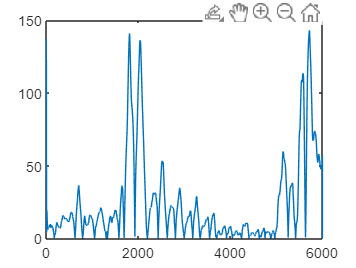

plot(diff1)

Y1 = zeros(outSize, testLen);
u1 = valData(1);
for t = 1:testLen 
    x = (1-a)*x + a*tanh( Win*[1;u1] + W*x );
    y = Wout*[1;u1;x];
    Y1(:,t) = y;
    % generative mode:
    %u1 = y;
    % this would be a predictive mode:
    u1 = valData(t+1);
end

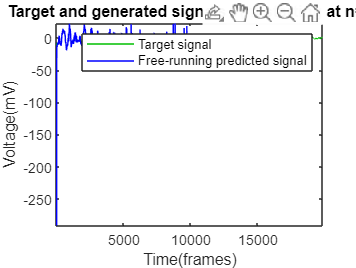

figure(2);
plot(valData, 'color', [0,0.75,0] );
hold on;
plot( Y1', 'b' );
hold off;
axis tight;
title('Target and generated signals y(n) starting at n=0');
xlabel('Time(frames)')
ylabel('Voltage(mV)')
legend('Target signal', 'Free-running predicted signal');

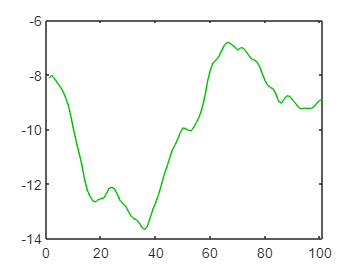

plot(valData(1:100+1), 'color', [0,0.75,0] );

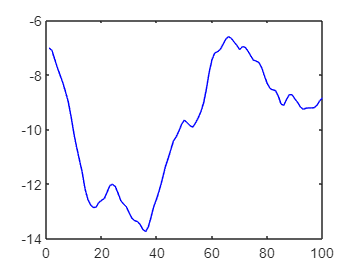

plot( Y1(1:100)', 'b' );

diff = zeros(1,6000);
for t=1:6000
    diff(1,t) = abs(valData(t)-Y1(t));
end

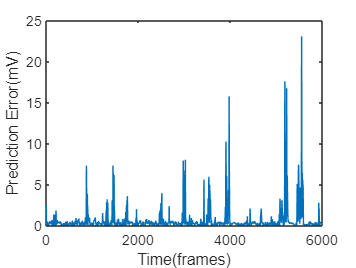

plot(diff(1,10:6000));
xlabel('Time(frames)')
ylabel('Prediction Error(mV)')

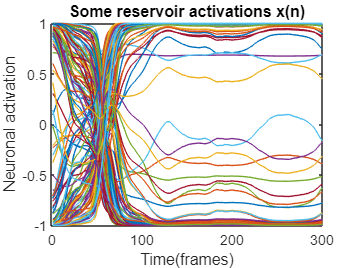

figure(2);
plot( X(255:400,1:300)' );
title('Some reservoir activations x(n)');
ylabel('Neuronal activation')
xlabel('Time(frames)')

movingAvg = zeros(1,34500)

movingAvg =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for t=11:34500
    subList = diff((t-10):(t+10));
    movingAvg(1,t)=mean(subList);
end

Index exceeds the number of array elements. Index must not exceed 6000.

plot(movingAvg)

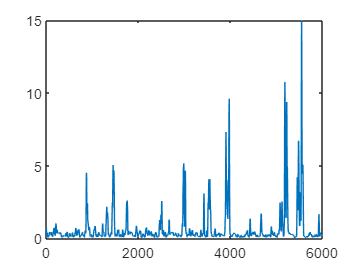

b = smoothdata(diff(1,10:6000));
plot(b)

%c = smoothdata(b);
c = smoothdata(c);
c = smoothdata(c);
c = smoothdata(c)

c =     0.4208    0.4208    0.4209    0.4209    0.4210    0.4210    0.4210    0.4211    0.4211    0.4212    0.4212    0.4212    0.4213    0.4213    0.4214    0.4214    0.4215    0.4215    0.4215    0.4216    0.4216    0.4217    0.4217    0.4218    0.4218    0.4219    0.4219    0.4219    0.4220    0.4220    0.4221    0.4221    0.4222    0.4222    0.4222    0.4223    0.4223    0.4224    0.4224    0.4225    0.4225    0.4226    0.4226    0.4227    0.4227    0.4227    0.4228    0.4228    0.4229    0.4229


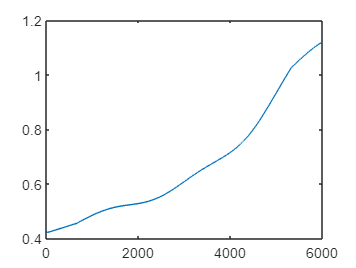

plot(c);

c(2,1:34500) = timeStamps(1:34500);

Index exceeds the number of array elements. Index must not exceed 31863.

c = c(1500:4100)

c =     0.5142    0.5142    0.5143    0.5143    0.5143    0.5144    0.5144    0.5144    0.5145    0.5145    0.5146    0.5146    0.5146    0.5147    0.5147    0.5147    0.5148    0.5148    0.5148    0.5149    0.5149    0.5149    0.5150    0.5150    0.5150    0.5151    0.5151    0.5152    0.5152    0.5152    0.5153    0.5153    0.5153    0.5154    0.5154    0.5154    0.5155    0.5155    0.5155    0.5156    0.5156    0.5156    0.5157    0.5157    0.5157    0.5158    0.5158    0.5158    0.5159    0.5159


storage = zeros(1,6000)
storage(1,:) = Y(1,:)
Y(1,:)=Y(2,:)
Y(2,:)=storage(1,:)
filename='generated.csv';
writematrix(Y', filename);

dim = 3;
[~,lag] = phaseSpaceReconstruction(Y,[],dim)

eRange = 42;
lyapunovExponent(Y,590,lag,dim,'ExpansionRange',eRange)

lyap = lyapunovExponent(Y, 59)

[m,i] = max(Wout)

plot(X(191,:))

Fs = 1178;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 9000;             % Length of signal
t = (0:L-1)*T;        % Time vector
F = fft(X(i,:));
P2 = abs(F/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('FFT of the largest weighted neuron activations')
xlabel('f (Hz)')
ylabel('|P1(f)|')

F = fft(Y);
P2 = abs(F/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('FFT of the data')
xlabel('f (Hz)')
ylabel('|P1(f)|')
[m, index] = max(P1);
datMax = f(index)

F = fft(X(min,:));
P2 = abs(F/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('FFT of the most negatively weighted neuron activations')
xlabel('f (Hz)')
ylabel('|P1(f)|')


peaks = zeros(1,100);
for i=1:100
    F = fft(X(i,:));
    P2 = abs(F/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    [m, mindex] = max(P1);
    peaks(i) = f(mindex);
end

avg = mean(peaks)